The objective is to create a 2D numerical solver for compressible fluid flow, solving the conservation equations (continuity, momentum, and energy) using the Kurganov-Tadmor central scheme.

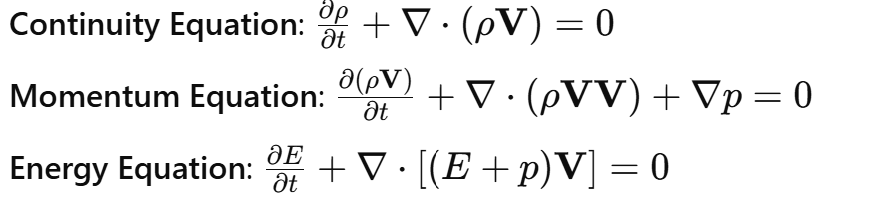

close; clc; format long g;

% Physical constants and parameters

factor = 1.0;                    % Factor to change the number of grid points, but keeps domain range constant (15 x 5) meters
iterations = 2000*floor(factor); % Total simulation iterations corrected for factor
n = 300*floor(factor) + 1;       % Number of grid points in x-direction
m = 100*floor(factor) + 1;       % Number of grid points in z-direction
dx = 0.05/factor;                % Grid spacing in x-direction, m
dz = dx;                         % Grid spacing in z-direction, m
dt = 1e-25;                      % Initial time step
kb = 1.381e-23;                  % Boltzmann constant (J/K)
v0 = 0;                          % Initial velocity (m/s)
time = 0;                        % Initialize simulation time
mass = 1.673e-27 * 20.0;         % Molecular mass of diatomic nitrogen (kg) = 28
                                 % Change the mass based on the following values:
                                 % o = 16, h = 1, o2 = 32, n = 14, n2 = 28
g = 1.4;                         % ratio of specific heats
p0 = 101325 * 1.0;               % Set p0 as 1 atm in Pa, or N/m^2
T0 = 300;                        % Initial temperature (K)
n0 = p0/(kb * T0);               % Initial particle density (particles/m^3)
aa = sqrt(g * kb * T0/mass);     % speed of sound
Mach = 1.8;                      % Choose Mach number
v1 = Mach * aa;                  % Set initial x velocity based on Mach number
disp(v1);                        % Display Velocity at chosen Mach number in m/s

          749.429908853736



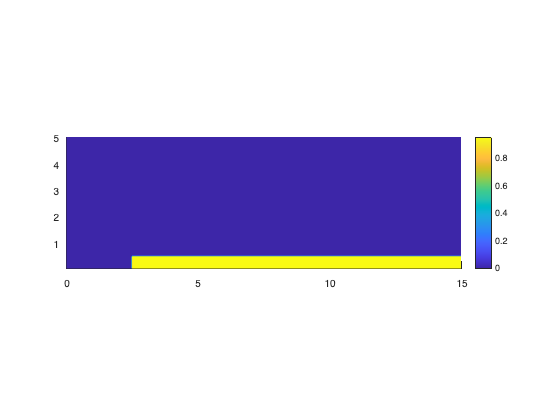

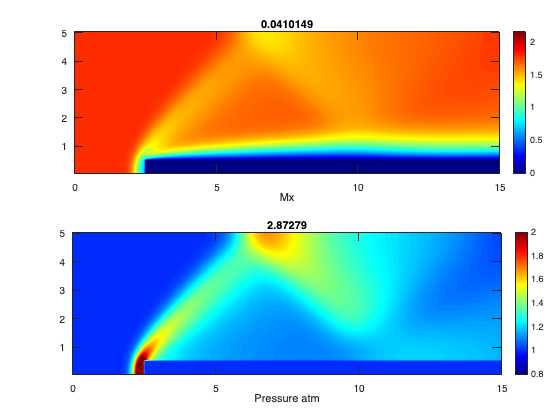

totaltime = 0.0;
timeout = 0.001;
nexttime = totaltime+timeout;


% Pre-allocate all arrays
rho = zeros(n, m);          % Density array
rhoo = zeros(n, m);         % Previous time step density array
rhou = zeros(n, m);         % Momentum in x-direction
rhouo = zeros(n, m);        % Previous time step momentum in x-direction
rhow = zeros(n, m);         % Momentum in z-direction
rhowo = zeros(n, m);        % Previous time step momentum in z-direction
E = zeros(n, m);            % Energy
Eo = zeros(n, m);           % Previous time step energy
p = zeros(n, m);            % Pressure
T = zeros(n, m);            % Temperature
mask = zeros(n,m);          % Mask function for solver
radius = zeros(n);

% Initialize arrays with initial conditions
for j = 1:m
    for i = 1:n
        rhoo(i, j) = n0 * mass;         % Uniform initial density
        rhouo(i, j) = rhoo(i, j) * v1;  % Initial momentum in x-direction
        rhowo(i, j) = rhoo(i, j) * v0;  % Initial momentum in z-direction
        T(i, j) = T0;                   % Initial temperature
        p(i, j) = rhoo(i, j) * kb * T(i, j) / mass; % Ideal gas law
        Eo(i, j) = rhouo(i, j)^2 / (2 * rhoo(i, j)) + ...
        rhowo(i, j)^2 / (2 * rhoo(i, j)) + 1.5 * p(i, j); % Total energy
    end
end
for j = 1:m
    for i = 1:n/4
        rhoo(i, j) = 1.0 * n0 * mass;                     % Uniform initial density
        rhouo(i, j) = rhoo(i, j) * v1;                    % Initial momentum in x-direction
        rhowo(i, j) = rhoo(i, j) * v0;                    % Initial momentum in z-direction
        T(i, j) = 1.0*T0;                                 % Initial temperature
        p(i, j) = rhoo(i, j) * kb * T(i, j) / mass;       % Ideal gas law
        Eo(i, j) = rhouo(i, j)^2 / (2 * rhoo(i, j)) + ...
        rhowo(i, j)^2 / (2 * rhoo(i, j)) + 1.5 * p(i, j); % Total energy
    end
end

% Setup Mask
xdata = 1:n;
xdata = (xdata-1) * dx;
ydata = 1:m;
ydata = ydata * dz;
%ydata = ydata - dz*(floor(m/2)+1);
mask(:,:)=0;

item = 1;      % 1 Blunt step up, 2 angle step up, 3 diamond wing
angle = 60.0;  % angle for step up 2, and half-angle for diamond wing 3

if (item == 1)
  ya = 0;
  for i = 1:n
   yl = 0.0;
   yu = 0.5; 

  for j = 1:m
    if (ydata(j) >= yl && ydata(j) <= yu && xdata(i) >= 2.5 && xdata(i) <= 20.0)
      mask(i,j) = 1;
    end
  end
  end
end

if (item == 2)
  
  yn = 12.0*atan(angle * 3.1415927 / 180.0);
  disp(yn);
  x1 = 2.5;
  y1 = 0.0;
  x2 = 15.0;
  y2 = yn;
  for i = 1:n
   for j = 1:m
       ya = y1 + ((y2-y1)/(x2-x1)) * (xdata(i)-x1);
       if (ya > 0.5) 
           ya = 0.5;
       end
    if (ydata(j) <= ya && xdata(i) >= 2.5 && xdata(i) <= 20.0)
      mask(i,j) = 1;
    end
   end
  end
end

   hold on;
   axis equal;
   contourf(xdata,ydata,mask',20,"LineStyle","none");colorbar;
   hold off;

   pause(1);

%mask setup inside
   for j = 1:m
    for i = 1:n
      if (mask(i,j) == 1)
        rhoo(i, j) = n0 * mass;                           % Uniform initial density
        rhouo(i, j) = rhoo(i, j) * v0;                    % Initial momentum in x-direction
        rhowo(i, j) = rhoo(i, j) * v0;                    % Initial momentum in z-direction
        T(i, j) = T0;                                     % Initial temperature
        p(i, j) = rhoo(i, j) * kb * T(i, j) / mass;       % Ideal gas law
        Eo(i, j) = rhouo(i, j)^2 / (2 * rhoo(i, j)) + ...
        rhowo(i, j)^2 / (2 * rhoo(i, j)) + 1.5 * p(i, j); % Total energy
      end
    end
   end
rho = rhoo;
rhou = rhouo;
rhow = rhowo;
E = Eo;

% Main loop for iterations
for loop = 1:iterations
    for j = 2:m-1
        for i = 2:n-1
          if(mask(i,j)==0)  
            % Compute local sound speed and velocities
            a0 = sqrt(5/3 * kb * T(i, j) / mass);
            a1 = sqrt(5/3 * kb * T(i-1, j) / mass);
            a2 = sqrt(5/3 * kb * T(i+1, j) / mass);
            a3 = sqrt(5/3 * kb * T(i, j-1) / mass);
            a4 = sqrt(5/3 * kb * T(i, j+1) / mass);
            u0 = rhouo(i, j) / rhoo(i, j);
            u1 = rhouo(i-1, j) / rhoo(i-1, j);
            u2 = rhouo(i+1, j) / rhoo(i+1, j);
            w0 = rhowo(i, j) / rhoo(i, j);
            w1 = rhowo(i, j-1) / rhoo(i, j-1);
            w2 = rhowo(i, j+1) / rhoo(i+1, j+1);

            % Continuity equation
            cr = max([abs(a0 + u0), abs(a0 - u0), abs(a2 + u2), abs(a2 - u2)]);
            cl = max([abs(a0 + u0), abs(a0 - u0), abs(a1 + u1), abs(a1 - u1)]);
            fr = 0.5 * (rhouo(i+1, j) + rhouo(i, j) - cr * (rhoo(i+1, j) - rhoo(i, j)));
            fl = 0.5 * (rhouo(i, j) + rhouo(i-1, j) - cl * (rhoo(i, j) - rhoo(i-1, j)));
            cu = max([abs(a0 + w0), abs(a0 - w0), abs(a4 + w2), abs(a4 - w2)]);
            cd = max([abs(a0 + w0), abs(a0 - w0), abs(a3 + w1), abs(a3 - w1)]);
            hr = 0.5 * (rhowo(i, j+1) + rhowo(i, j) - cu * (rhoo(i, j+1) - rhoo(i, j)));
            hl = 0.5 * (rhowo(i, j) + rhowo(i, j-1) - cd * (rhoo(i, j) - rhoo(i, j-1)));
            rho(i, j) = rhoo(i, j) - (dt/dx) * (fr - fl) - (dt/dz) * (hr - hl);
            
            % Momentum Equation in x direction
            fr = 0.5*(rhouo(i + 1,j)*rhouo(i + 1,j)/rhoo(i + 1,j) + p(i + 1,j) + ...
            rhouo(i,j)*rhouo(i,j)/rhoo(i,j) + p(i,j) - cr*(rhouo(i + 1,j) - ...
            rhouo(i,j)));
            fl = 0.5*(rhouo(i,j)*rhouo(i,j)/rhoo(i,j) + p(i,j) + rhouo(i - 1,j)* ...
            rhouo(i - 1,j)/rhoo(i - 1,j) + p(i - 1,j) - cl*(rhouo(i,j) - ...
            rhouo(i - 1,j)));
            hr = 0.5*( rhouo(i,j+1)*rhowo(i,j+1)/rhoo(i,j+1) + rhouo(i,j)* ...
            rhowo(i,j)/rhoo(i,j)-cu*( rhouo(i,j+1) - rhouo(i,j) ) );
            hl = 0.5*( rhouo(i,j)*rhowo(i,j)/rhoo(i,j) + rhouo(i,j-1)* ...
            rhowo(i,j-1)/rhoo(i,j-1)-cd*( rhouo(i,j) - rhouo(i,j-1) ) );
            rhou(i,j) = rhouo(i,j) - (dt/dx)*(fr - fl) - (dt/dz)*(hr - hl);
            
            % Momentum Equation in z direction
            fr = 0.5*(rhouo(i + 1,j)*rhowo(i + 1,j)/rhoo(i + 1,j) + ...
            rhouo(i,j)*rhowo(i,j)/rhoo(i,j) - cr*(rhowo(i + 1,j) - rhowo(i,j)));
            fl = 0.5*(rhouo(i,j)*rhowo(i,j)/rhoo(i,j) + rhouo(i - 1,j)* ...
            rhowo(i - 1,j)/rhoo(i - 1,j) - cl*(rhowo(i,j) - rhowo(i - 1,j)));
            hr = 0.5*(rhowo(i,j + 1)*rhowo(i,j + 1)/rhoo(i,j + 1) + ...
            p(i,j + 1) + rhowo(i,j)*rhowo(i,j)/rhoo(i,j) + p(i,j) - ...
            cu*(rhowo(i,j + 1) - rhowo(i,j)));
            hl = 0.5*(rhowo(i,j)*rhowo(i,j)/rhoo(i,j) + p(i,j) + ...
            rhowo(i,j - 1)*rhowo(i,j - 1)/rhoo(i,j - 1) + p(i,j - 1) - ...
            cd*(rhowo(i,j) - rhowo(i,j - 1)));
            rhow(i,j) = rhowo(i,j) - (dt/dx)*(fr - fl) - (dt/dz)*(hr - hl);
            
            % Energy Equation
            fr = 0.5*((Eo(i + 1,j) + p(i + 1,j))*rhouo(i+1,j)/rhoo(i+1,j) + ...
            (Eo(i,j) + p(i,j))*rhouo(i,j)/rhoo(i,j) -cr*( Eo(i+1,j) - Eo(i,j)));
            fl = 0.5*( (Eo(i,j) + p(i,j))*rhouo(i,j)/rhoo(i,j) + (Eo(i - 1,j) + ...
            p(i - 1,j))*rhouo(i - 1,j)/rhoo(i - 1,j) - cl*(Eo(i,j) - Eo(i - 1,j)));
            hr = 0.5*((Eo(i,j + 1) + p(i,j + 1))*rhowo(i,j + 1)/rhoo(i,j + 1) + ...
            (Eo(i,j) + p(i,j))*rhowo(i,j)/rhoo(i,j) - cu*(Eo(i,j + 1) - Eo(i,j)));
            hl = 0.5*((Eo(i,j) + p(i,j))*rhowo(i,j)/rhoo(i,j) + (Eo(i,j - 1) + ...
            p(i,j - 1))*rhowo(i,j - 1)/rhoo(i,j - 1) - cd*(Eo(i,j) - Eo(i,j - 1)));
            E(i,j) = Eo(i,j) - (dt/dx)*(fr - fl) - (dt/dz)*(hr - hl);
          end
        end
    end
    

    % Update arrays and apply reflective boundary conditions
    rhoo = rho;
    rhoo(1,:) = rhoo(2,:);          % Left edge
    rhoo(n,:) = rhoo(n-1,:);        % Right edge
    rhoo(:,1) = rhoo(:,2);          % Top edge
    rhoo(:,m) = rhoo(:,m-1);        % Bottom edge
    
    rhouo = rhou;
    rhouo(1,:) = rhou(2,:);
    rhouo(n,:) = rhou(n-1,:);
    rhouo(:,1) = rhou(:,2);
    rhouo(:,m) = rhou(:,m-1);
    
    rhowo = rhow;
    rhowo(1,:) = rhow(2,:);
    rhowo(n,:) = rhow(n-1,:);
    rhowo(:,1) = -rhow(:,2);
    rhowo(:,m) = -rhow(:,m-1);
    
    Eo = E;
    Eo(1,:) = E(2,:);
    Eo(n,:) = E(n-1,:);
    Eo(:,1) = E(:,2);
    Eo(:,m) = E(:,m-1);

    %BC setup inside
    for j = 1:m
     for i = 1:2
         %if (ydata(j)>0.75 || ydata(j)<-0.75)
          rhoo(i, j) = n0 * mass * 1.0;                     % Uniform initial density
          rhouo(i, j) = rhoo(i, j) * v1;                    % Initial momentum in x-direction
          rhowo(i, j) = rhoo(i, j) * v0;                    % Initial momentum in z-direction
          T(i, j) = T0 * 1.0;                               % Initial temperature
          p(i, j) = rhoo(i, j) * kb * T(i, j) / mass;       % Ideal gas law
          Eo(i, j) = rhouo(i, j)^2 / (2 * rhoo(i, j)) + ...
          rhowo(i, j)^2 / (2 * rhoo(i, j)) + 1.5 * p(i, j); % Total energy
         %end
     end
    end

    p = (Eo - rhouo.*rhouo./(2.*rhoo) - rhowo.*rhowo./(2.*rhoo)).*2./3;
    T = p./((rhoo./mass).*kb);

    ss = sqrt(g * kb * T/mass);     % speed of sound
    time = time + dt;
    
    % Calculate the maximum values as per the formula
    max_dx_term = max(max(abs(rhouo ./ rhoo) + sqrt(1.667 * kb * T / mass)));
    max_dz_term = max(max(abs(rhowo ./ rhoo) + sqrt(1.667 * kb * T / mass)));
    
    % Calculate dt
    dt = 0.5 * min(dx / max_dx_term, dz / max_dz_term);

    totaltime = totaltime + dt;
    if totaltime > nexttime
        
        tiledlayout(2,1);
        
        ax1 = nexttile;
        contourf(xdata,ydata,(rhouo'./rhoo')./ss', 200 , "LineStyle","none")  %(rhouo'./rhoo')./ss'
        %contourf(xdata,ydata,p', 200 , "LineStyle","none")  %(rhouo'./rhoo')./ss'
        colorbar
        colormap(ax1,"jet")
        title(totaltime)
        xlabel('Mx')
        axis equal
        %xlim([0.02 0.8])
        clim([0,1.2*Mach])
        
        ax2 = nexttile;
        contourf(xdata,ydata,(p'/p0), 200 , "LineStyle","none")  %(rhouo'./rhoo')./ss'
        %contourf(xdata,ydata,rhowo'./rhoo', 200 , "LineStyle","none")  %(rhouo'./rhoo')./ss'
        colorbar
        colormap(ax2,"jet")
        title(max(p/p0, [], 'all'))
        xlabel('Pressure atm')
        %xlim([0.02 0.8])
        clim([0.8,2.0])
        
        pause(0.02);
        %disp(loop);
        nexttime = nexttime + timeout;
    end
end

%contourf(mask',20,"LineStyle","none");
%contourf((rhouo'./rhoo')./ss', 200 , "LineStyle","none"); colorbar;
%contourf(T', 50 , "LineStyle","none"); colorbar;
%contourf(log10(p'), 50 , "LineStyle","none"); colorbar;
%contourf(rhoo', 50 , "LineStyle","none"); colorbar;